# 平滑窗

平滑窗（锐化窗）是一个从中心峰值点向两侧衰落的实函数，在信号处理中用来缓解有限长度信号的**截断影响。**

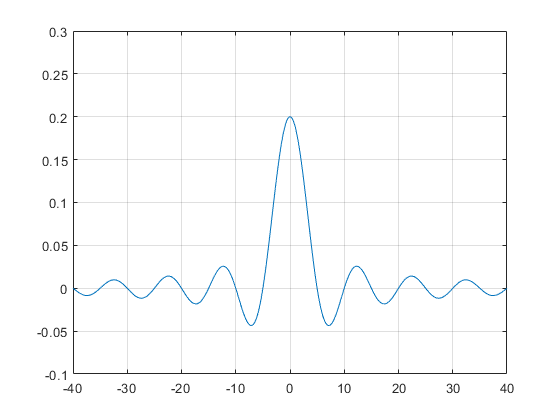

N = 20000;
omega = 0.2*pi;
t = -100:1/N:100-1/N;

st = sin(omega*t)./(pi*t);

plot(t,st)
axis([-40 40,-0.1 0.3])
grid on

Kaiser窗

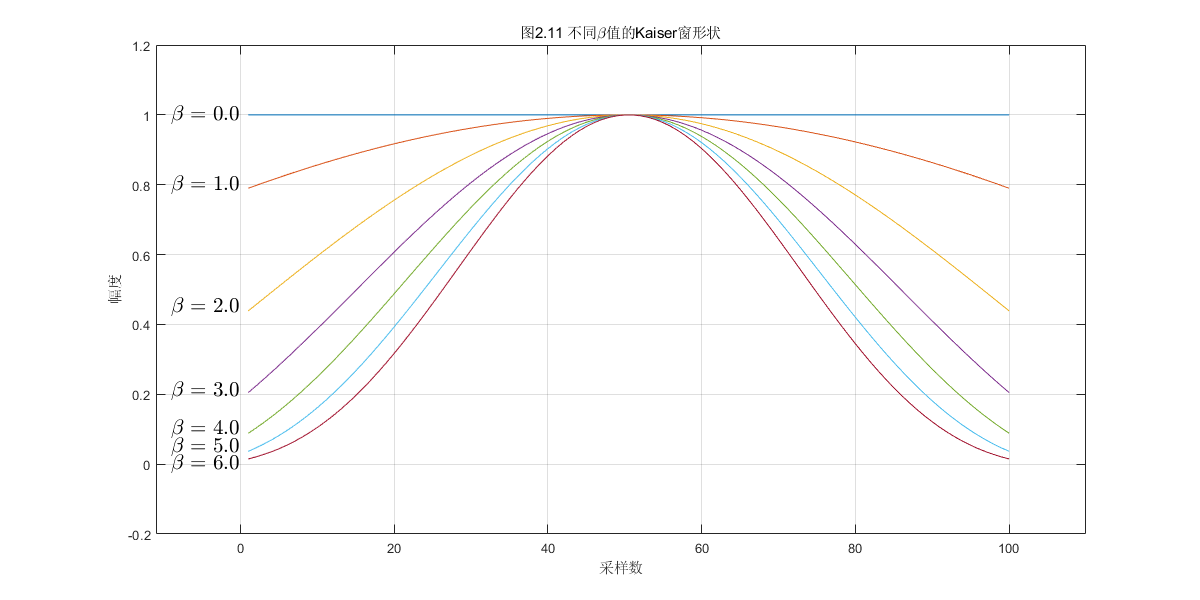

N = 100;
beta = [0,1,2,3,4,5,6];

hw = [];
pslr = [];
tempn = [];

figure,set(figure,'position',[100,100,1200,600]);
for i = 1:1:7
    % 生成kauser窗
    A = kaiser(N,beta(i));
    % 绘制Kaiser窗
    plot(A),hold on
    % 对kaiser窗进行傅里叶变换
    temp = fft(A,2^14);
    temp = 20*log10(abs(temp)./max(abs(temp)));
    tempn = [tempn,temp];
    % 提取kaiser窗的3dB波束宽度
    [hwn,locleft,locright] = get_hw(temp);
    hw = [hw,hwn];
    % 提取Kaiser窗的峰值旁瓣比
    [pslrn] = get_pslr(temp);
    pslr = [pslr,pslrn];
end

title('图2.11 不同\beta值的Kaiser窗形状'),xlabel('采样数'),ylabel('幅度')
axis([-11 110,-0.2 1.2])
grid on

text('Interpreter','latex','String','$\beta=0.0$','Position',[-9 1.00],'FontSize',16);
text('Interpreter','latex','String','$\beta=1.0$','Position',[-9 0.80],'FontSize',16);
text('Interpreter','latex','String','$\beta=2.0$','Position',[-9 0.45],'FontSize',16);
text('Interpreter','latex','String','$\beta=3.0$','Position',[-9 0.21],'FontSize',16);
text('Interpreter','latex','String','$\beta=4.0$','Position',[-9 0.10],'FontSize',16);
text('Interpreter','latex','String','$\beta=5.0$','Position',[-9 0.05],'FontSize',16);
text('Interpreter','latex','String','$\beta=6.0$','Position',[-9 0.00],'FontSize',16);


tempn

tempn =          0         0         0         0         0         0         0
   -0.0005   -0.0005   -0.0004   -0.0004   -0.0003   -0.0003   -0.0002
   -0.0021   -0.0020   -0.0017   -0.0014   -0.0012   -0.0010   -0.0009
   -0.0048   -0.0045   -0.0038   -0.0032   -0.0027   -0.0023   -0.0020
   -0.0085   -0.0080   -0.0068   -0.0057   -0.0047   -0.0040   -0.0035
   -0.0133   -0.0125   -0.0107   -0.0089   -0.0074   -0.0063   -0.0054
   -0.0192   -0.0180   -0.0154   -0.0127   -0.0106   -0.0090   -0.0078
   -0.0261   -0.0245   -0.0209   -0.0174   -0.0145   -0.0123   -0.0107
   -0.0341   -0.0320   -0.0273   -0.0227   -0.0189   -0.0161   -0.0139
   -0.0432   -0.0405   -0.0346   -0.0287   -0.0239   -0.0204   -0.0176


tempn(:,1)

ans =          0
   -0.0005
   -0.0021
   -0.0048
   -0.0085
   -0.0133
   -0.0192
   -0.0261
   -0.0341
   -0.0432


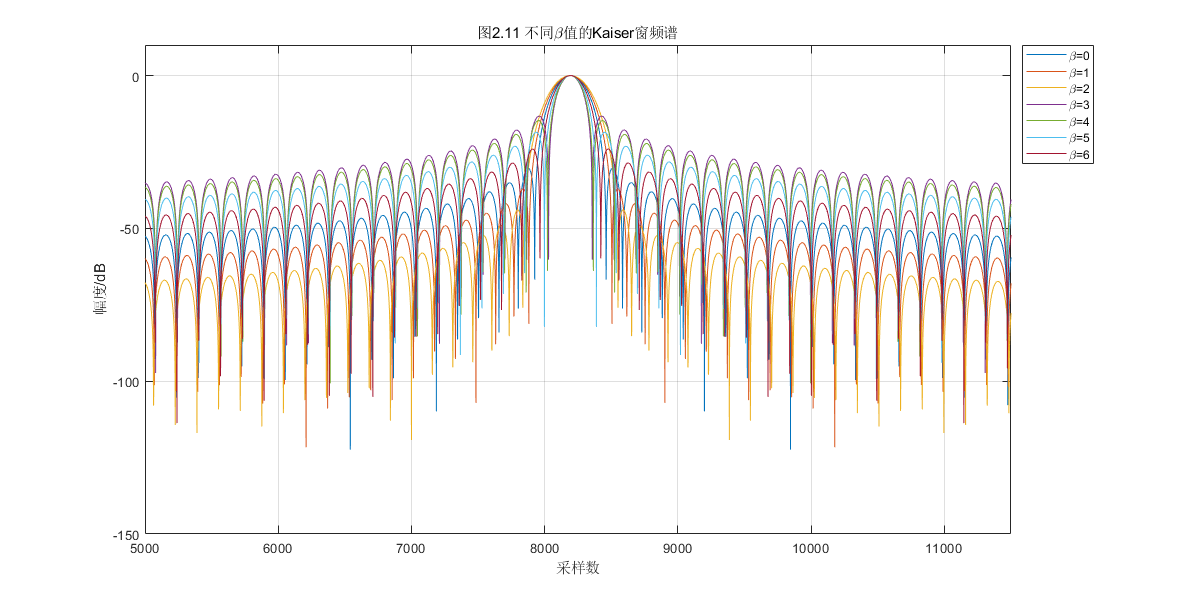

figure,set(figure,'position',[100,100,1200,600]);
plot(fftshift(tempn))
title('图2.11 不同\beta值的Kaiser窗频谱'),xlabel('采样数'),ylabel('幅度/dB')
axis([5000 11500,-150 10])
grid on
set(legend,'Location','NorthEastOutside')
legend('\beta=0','\beta=1','\beta=2','\beta=3','\beta=4','\beta=5','\beta=6')

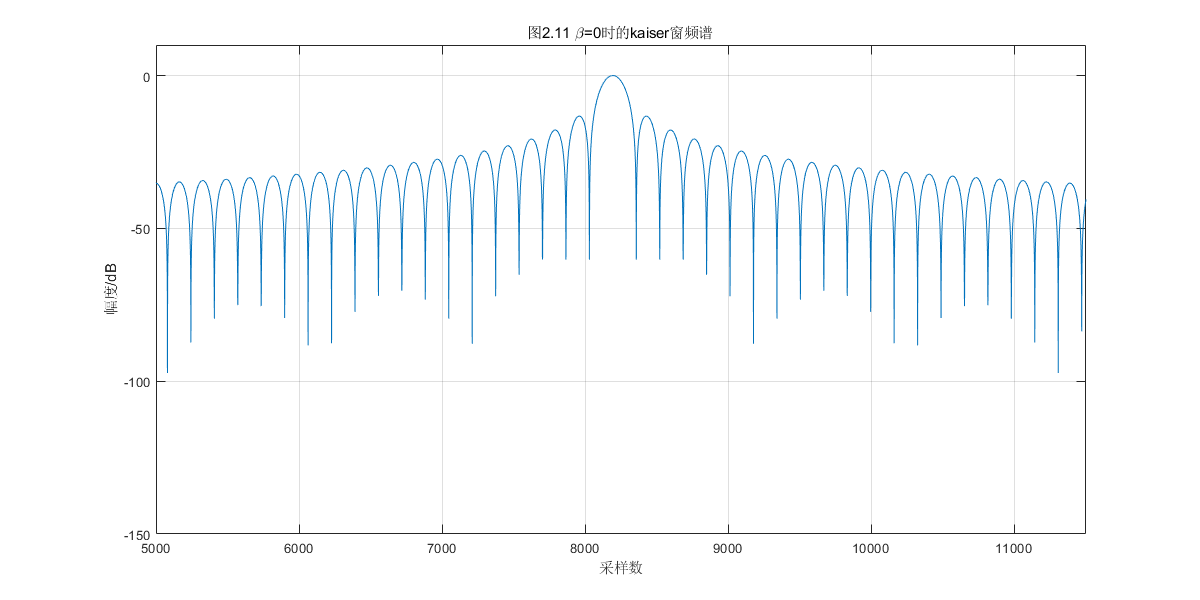


figure,set(figure,'position',[100,100,1200,600]);
plot(fftshift(tempn(:,1)))
title('图2.11 \beta=0时的kaiser窗频谱'),xlabel('采样数'),ylabel('幅度/dB')
axis([5000 11500,-150 10])
grid on

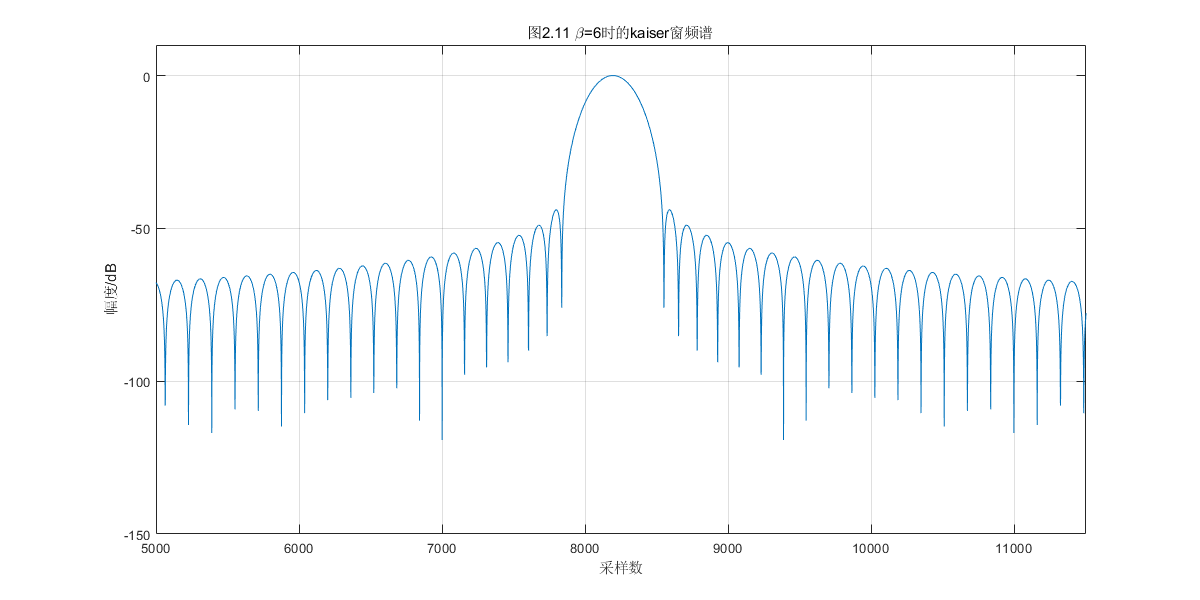


figure,set(figure,'position',[100,100,1200,600]);
plot(fftshift(tempn(:,7)))
title('图2.11 \beta=6时的kaiser窗频谱'),xlabel('采样数'),ylabel('幅度/dB')
axis([5000 11500,-150 10])
grid on


figure,set(figure,'position',[100,100,1200,600]);
% 3dB宽度展宽比
hw

hw =     72    75    81    90    99   107   116


subplot(121),plot((hw./hw(1)-1)*100)
title('(a)3dB宽度展宽比'),xlabel('Kaiser窗\beta'),ylabel('展宽比')
grid on
% 峰值旁瓣比
pslr

pslr =   -13.2587  -14.6917  -18.5610  -24.0197  -30.3428  -37.0492  -43.9175


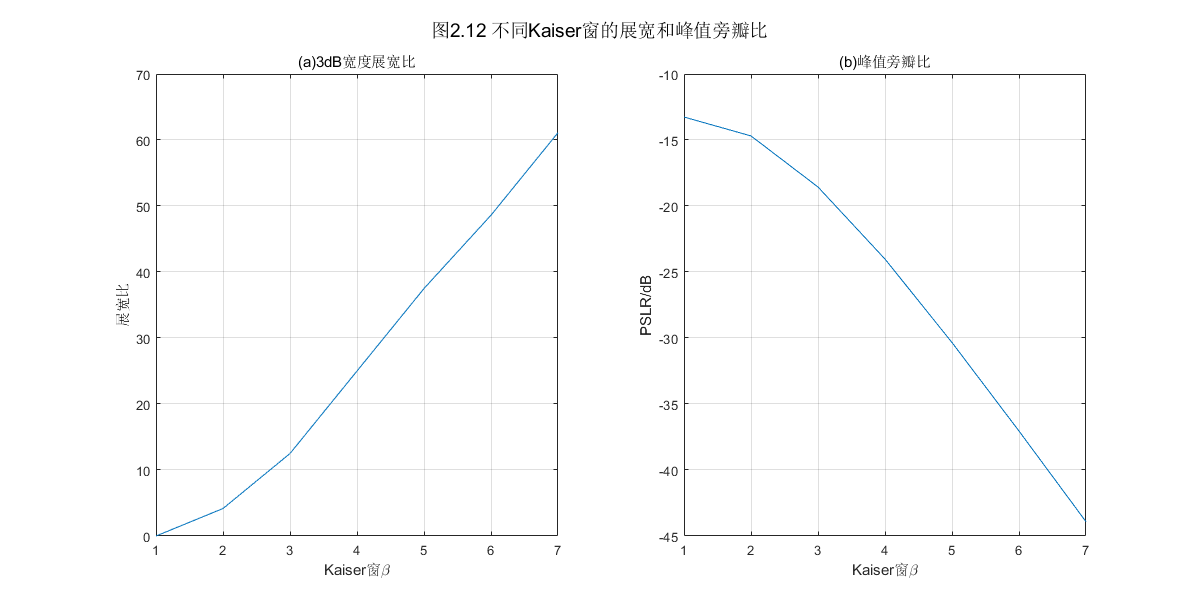

subplot(122),plot(pslr)
title('(b)峰值旁瓣比'),xlabel('Kaiser窗\beta'),ylabel('PSLR/dB')
grid on
suptitle('图2.12 不同Kaiser窗的展宽和峰值旁瓣比')

提取3dB波束宽度

function [hw,locleft,locright] = get_hw(Af)
    % 找到Af的最大位置
    [~,locmax] = max(Af);
    % 找到locmax左边最接近-3dB的位置
    [~,locleft] = min(abs(Af(1:locmax)+3));
    % 找到locmax右边最接近-3dB的位置
    [~,locright] = min(abs(Af(locmax:end)+3));
    locright = locright + locmax - 1;
    % 得到3dB波束宽度
    hw = locright-locleft;
end

提取峰值旁瓣比

function [pslr] = get_pslr(Af)
    % 找到所有的pesks
    peaks = findpeaks(Af);
    % 对peaks进行排序
    peaks = sort(peaks,'descend');
    % 得到第一旁瓣
    pslr = peaks(2);
end